# Adaptive Quasi-Monte Carlo for Bayesian Inference

## Purpose

This MATLAB script efficiently calculates the posterior mean of a model parameter using Bayesian Inference and Monte Carlo methods.  The ratio of multivariate integrals that gives the posterior mean (introduced below) is something that cannot be evaluated anlaytically.  Therefore, one way to go about evaluating the ratio is using automatic Monte Carlo methods.  In order to do this, a density must be chosen for sampling.  This script will explore a few different densities and determine which density is the most efficient at satisfying some desired level of tolerance.

## Background

**Frequentist Statistics**

Frequentist Statistics are a very common method for estimating parameters.  The method is fairly simple and straightforward, providing a procedure that many people can easily understand.  The general idea behind frequentist statistics is that the unknown parameters being estimated are fixed.  Therefore, reasonable estimates for these parameters can be made via sampling from a certain population.  

The problem with this method is that different samples can sometimes lead to very different estimations.  As there is variation in the sample population, the possibility exists that each sample taken looks very different from the next.  Since the estimates are solely based off of the sample taken, there is no guarantee that an estimation created from one sample will look anything like an estimation created from another sample, let alone be similar to the true parameter value.  There are of course numerous procedures supplementary to frequentist statistics that can aid in reducing this variation, making it more conceivable that the obtained estimation values are somewhat close to the true parameter values.  However, no matter what, this variation always remains an issue to some degree.  One way to work around this variation problem is to use Bayesian statistics in lieu of frequentist statistics. 

**Bayesian Statistics**

Bayesian Statistics is a concept increasing in popularity.  In short, Bayesian inference is an alternate appraoch used to estimate unknown parameters of a distribution.  Not only is sample evidence considered, but also an individual's prior beliefs about the distribution are taken into account.

One of the biggest differences between frequentist statistics and Bayesian statistics is that while the parameters being estimated in Bayesian statistics are still unknown, they are not fixed as they are in frequentist statistics.  Rather, the parameters being estimated are random variables following a certain distribution.  Additionally, Bayesian estimates are based off of more than just sampling.  They are also based off of something called a prior distribution, which does not necessarily require any data to formulate.  The prior distribution is a person's beliefs about the parameters in question before any sampling is done.  

Once a prior is formed, sampling may begin.  From the sample taken, a likelihood function is formed and its respective curve is graphed.  A likelihood function is a function of the parameters being estimated.  In the case of Bayesian inference, the likelihood function represents how likely it is that the parameters take on certain values given the data that was observed via sampling.  

Once the likelihood function is set up, a posterior distribution is drafted.  This posterior distribution represents a person's updated beliefs about the parameters after sampling is completed and the results are analyzed.  In essence, one performing Bayesian inference begins with an original set of prior beliefs and ends up with a revised set of posterior beliefs that they now see as true.  The posterior distribution is generally a product of the prior distribution and the developed likelihood function, with certain weights attached to each depending on the situation.  For instance, if the prior distribution was given considerable thought combined with a lot of previous evidence and intuition, one is generally more confident that their prior distribution closely resembles the true parameter values.  Essentially, the posterior distribution will look more like the prior distribution if the prior is more intricate than it would if the prior was merely generated randomly.  In terms of the evidence and sampling, the emphasis is often closely related to the size of the sample taken.  More emphasis or weight may be put on the likelihood function than the prior distribution if a larger sample is taken, whereas less weight may follow if the sample taken is substantially smaller.

As an example, consider the flipping of a coin. Let the parameter $\theta$ represent the percentage of the coin flips that result in heads.  In this case, there is a large quantity of preexisting knowledge and research about this problem, meaning that a prior distribution more accurate than a random guess can be developed.  Virtually all previous evidence that exists supports $0.50$ as the true value for $\theta$.  Thus, some prior probability distribution whose center is $0.50$ can be developed and used.  Next, sampling would be done in the form of flipping a coin some number of times and recording how many times the coin showed heads.  Since the prior is backed up by a lot of preexisting evidence and research, one can feel quite confident about the validity of the prior distribution.  As such, when developing the posterior distribution, more emphasis will most likely be put on the prior distribution than the likelihood function.  This means that the sample taken does not necessarily have to be very large, say merely of size 20.  Once the sample data is recorded, the likelihood function can be produced.  Say that 20 coin flips results in 12 heads, or an approximation for $\theta$ of $0.60$.  From this, one can calculate how likely it is that the true value of $\theta$ is $0.40$, $0.50$, $0.60$, etc, given that 20 coin flips resulted in 12 heads.  This is done for all $\theta \in [0, 1]$ using the rules of conditional probability.  All of these values together represent a likelihood function, whose highest probability in this case would correspond to $\theta=0.60$.  Lastly, the posterior distribution can be formulated as a combination of the prior distribution and likelihood function.  As the prior distribution is centered around $\theta = 0.5$ and the likelihood function is centered around $\theta = 0.6$, the posterior distribution will have a center somewhere in the range $0.50 \leq \theta \leq 0.60$.  Since the prior was developed very intricately and a somewhat small sample was taken, the posterior distribution will be calculated as a product that puts a larger weight on the prior than the likelihood function.  Therefore, while the center of the posterior distribution will be somewhere within $0.50 \leq \theta \leq 0.60$, it is more likely to be closer to $0.50$, the center of the prior, than $0.60$, the center of the likelihood function.  

**Why Choose Bayesian Inference?**

In summary, comparing inferential statistics and Bayesian statistics, each has advantages and disadvantages.  Inferential statistics can be easier to carry out since it only requires sampling and no prior distribution.  However, for this same reason, estimates using inferential statistics are often more likely than Bayesian estimates to experience variation in parameter values due to the non-uniformity of sample populations.  As variation is not desirable, many prefer using Bayesian statistics over inferential statistics due to its potential of decreased variation.  

**Hessian Matrix**

One concept that appears in our density choices is the Hessian matrix.  In short, a Hessian matrix is a matrix of all of the second-order partial derivatives of some function.  Additionally, the matrix is always a square matrix.  Consider the general form of a Hessian matrix, as follows:

Let some function $f$ have domain $x \in \mathbb{R}^n$ and codomain $f(x) \in \mathbb{R}$.  The domain of $f$ indicates that there are $n \cdot n$, or $n^2$ second partial derivatives of $f$.  Thus, the Hessian matrix of $f(x)$ will be $n \times n$.


$$\textbf{H} =

\left[ \begin{array} {cccc}
\frac {\partial^2 f} {\partial x_1^2 & \frac {\partial^2 f} {\partial x_1 \partial x_2 & \cdot & \cdot & \cdot & \frac {\partial^2 f} {\partial x_1 \partial x_n} \\

\frac {\partial^2 f} {\partial x_1 \partial x_2 & \frac {\partial^2 f} {\partial x_2^2 & \cdot & \cdot & \cdot & \frac {\partial^2 f} {\partial x_2 \partial x_n} \\

\cdot & \cdot & \cdot & & & \cdot \\
\cdot & \cdot & & \cdot & & \cdot\\
\cdot & \cdot & & & \cdot & \cdot \\

\frac {\partial^2 f} {\partial x_n \partial x_1 & \frac {\partial^2 f} {\partial x_n^2 \partial x_2} & \cdot & \cdot & \cdot & \frac {\partial^2 f} {\partial x_n^2} \\

\end{array} \right]$$


By looking at the Hessian matrix in its general form, it is apparent that the entry of the $i^{th}$ row, $j^{th}$ column of the matrix will be 


$$\textbf{H}_{i, j} = \frac {\partial^2 f} {\partial x_i \partial x_j$$


This also tells us that all entries on the diagonal of the Hessian matrix will be second-order derivatives with respect to one variable, whereas the off-diagonal entries of the matrix will be mixed partial derivatives of order one in each coordinate.

**Quasi-Monte Carlo Cubature Rule**

The quasi-Monte Carlo cubature rule approximates an integral as follows:


$$\int_{[0, 1]^{d+1}}f(\mathbf{\mathit{x}}) \mathrm{d} \mathbf{\mathit{x}}\approx \frac{1}{n} \sum_{i=0}^{n-1}f(\mathbf{\mathit{x}}_i) $$


where $\{x_i\}_{i=0}^{n-1}$ comes from a low discrepancy sequence.

**Low Discrepancy Sequences**

Low discrepancy sequences are **correlated **sequences whose empirical distribution matches the target distribution better than one of an IID sequence.  

For illustration, see the following plots, the first generated using i.i.d. uniform criterion with a standard normal transformation, the second using sobol sequences, and the third using lattice points.  Note that both the Sobol sequences and lattice points are low discrepancy sequences.

The following code creates a plot of 128 points that were generated first using i.i.d. uniform variables and then transformed to the standard normal distribution.

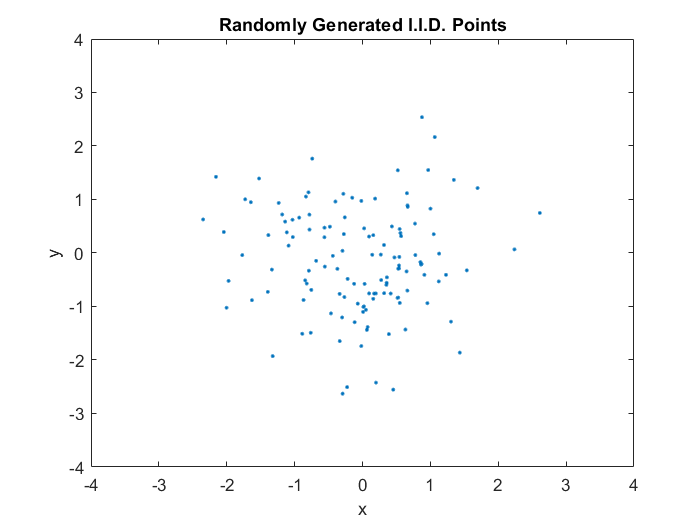

uniform=rand(128, 2);
iidnormal=norminv(uniform);
plot(iidnormal(:, 1), iidnormal(:, 2), '.')
axis([-4 4 -4 4])
title('Randomly Generated I.I.D. Points')
xlabel('x')
ylabel('y')

The following code creates a plot of 128 points generated using Sobol sequences and then undergoing the standard normal transformation.

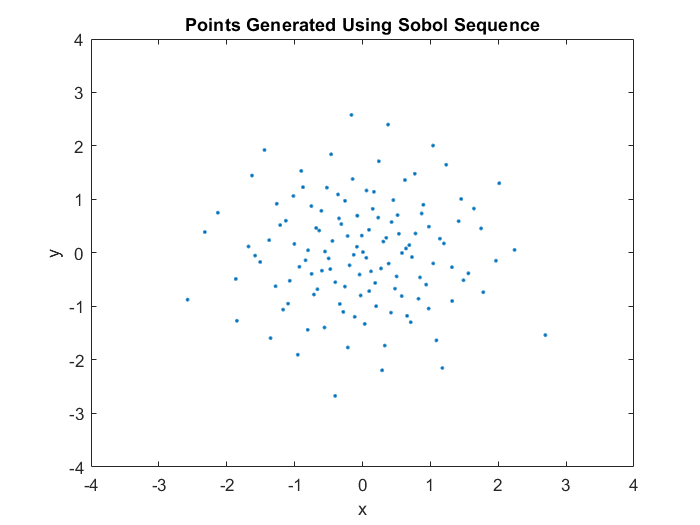

sobolp=scramble(sobolset(2), 'MatousekAffineOwen');
sobolptsGauss=norminv(net(sobolp, 128));
plot(sobolptsGauss(:,1), sobolptsGauss(:,2), '.')
axis([-4 4 -4 4])
title('Points Generated Using Sobol Sequence')
xlabel('x')
ylabel('y')

The following code creates a plot of 128 points generated using Lattice points and then undergoing the standard normal transformation.

## Problem Formulation

**The Posterior Mean as a Ratio of Integrals**

One of the main ideas behind this live script is the following estimator commonly used for Bayesian inference, representing the posterior mean of the model parameter:


$$\hat{\beta}_j=\frac{\int_{\mathbb{R}^{d+1}}b_jL(\mathbf{\mathit{b}})\pi(\mathbf{\mathit{b}}) \, \mathrm{d} \mathbf{\mathit{b}}}{\int_{\mathbb{R}^{d+1}}L(\mathbf{\mathit{b}})\pi(\mathbf{\mathit{b}})\, \mathrm{d}\mathbf{\mathit{b}}} =: \frac{\mu_j}{\mu}, ~for\ j=0, 1, 2,\ldots, d$$


where

$\hat{\beta_j }$ is a component of $\beta^{ˆ}$, the unknown parameter(s)

$L\left(\mathit{\mathbf{b}}\right)$ is the likelihood function given the observed data

$\pi \left(\mathit{\mathbf{b}}\right)$ is a prior distribution

This ratio of integrals, as discussed in the beginning of this paper, is impossible to evaluate analytically, even with explicit expressions for $L(b)$ and $\pi(b)$.  Therefore, we will explore evaluating these integrals using Monte Carlo and quasi-Monte Carlo methods along with various sample densities.

**Logistic Regression**

**Bernoulli Distribution**

We are going to perform logistic regression using Bayesian inference, where each $t_i$ is assumed to be an independently, identically distributed Bernoulli variable.  The Bernoulli variables have the following distribution:


$$t_i ~ {\tilde} ~ \text{Ber}

\left(\frac{\exp{\left(\beta_0+\sum_{j=1}^d\beta_j s_{ij}\right)}}

{1+\exp \left({{\beta_0+\sum_{j=1}^d\beta_js_{ij}}}\right)}\right), 

~\text{for} ~i=1, 2, \dots , M$$


A Bernoulli distribution is a discrete probability distribution that has two outcomes, denoted "success" and "failure."  A success is denoted by $t_i=1$ and a failure is denoted by $t_i=0$.  In a typical Bernoulli distribution of the form $\text{Ber}(p)$, $p$ is the probability of a success and $(1-p)$ is the probability of failure.  It should be noted that $0 \leq p \leq 1$.

Therefore, in our case, the probability of success is $\left( \frac{ \exp \left( {\beta_0+ \sum_{j=1}^d\beta_j s_{ij}} \right) }

{1+ \exp \left( {\beta_0+ \sum_{j=1}^d\beta_j s_{ij}} \right) }

\right) $.

**Likelihood Function**

The general formula for the likelihood function of i.i.d. Bernoulli variables $\text{Ber}(p)$ takes the form 


$$\begin{array} {rcl}

L(p | x_1, \dots , x_n) & =& p^{x_1} (1-p)^{1-x_1} \cdot \dots \cdot p^{x_n} (1-p)^{1-x_n} \\
& = & \prod _{i=1}^n p^{x_i} (1-p)^{1-x_i}

\end{array}$$


Using this format for the likelihood of a Bernoulli distribution and the fact that $t_i ~ {\tilde} ~ \text{Ber}

\left(\frac{\exp{\left(\beta_0+\sum_{j=1}^d\beta_j s_{ij}\right)}}

{1+\exp \left({{\beta_0+\sum_{j=1}^d\beta_js_{ij}}}\right)}\right)$, we arrive at the following likelihood function:


$$L(\mathbf{\mathit{\beta}})=\prod_{i=1}^M

\left(\frac{\exp{\left({\beta_0+\sum_{j=1}^d\beta_js_{ij}}\right)}}{1+\exp{\left ({\beta_0+\sum_{j=1}^d\beta_js_{ij}}\right )}}\right)^{t_i} 
\ 
\left(1-\frac{\exp{\left ({\beta_0+\sum_{j=1}^d\beta_js_{ij}}\right)}}{1+\exp{\left ({\beta_0+\sum_{j=1}^d\beta_js_{ij}}\right )}}\right)^{1-t_i}$$


This function will be evaluated for various samples that are taken.  The distribution from which these samples are derived will be discussed later.

**Prior Distribution**

Before we take any samples, we must decide on a prior distribution of our parameters in order to execute Bayesian inference.  For simplicity, we choose the standard normal distribution with respect to our parameters $\beta_j, ~ j=0, \dots , d$.  Here is the corresponding probability density function, defined now as the prior of $\mathbf{\mathit{\beta}}$:


$$\pi(\beta)=\frac{\exp{\left({-\frac{1}{2}\mathbf{\mathit{\beta}}^T\mathbf{\mathit{\beta}}}\right )}}{\sqrt{(2\pi)^{d+1}}}$$


**Posterior Distribution**

Using the defined choices for the prior distribution and likelihood function of $\beta$, we must calculate the following integrals for $\mu$ and $\mu_j$:


$$\mu=\int_{\Re^{d+1}}L(b)\pi(b)d(b), ~~\mu_j=\int_{\Re^{d+1}}b_jL(b)\pi(b)db$$


It is these integrals that will then be used to calculate our posterior estimates $\hat{\beta}_j$ (above) by the ratios $\frac{\mu_j}{\mu}, ~ j=0, \dots , d$.  However, as previously mentioned, these ratios of integrals cannot be solved analytically.  As a result, in order to evaluate the ratios of integrals, we must choose some density $\rho(b)$ in which we will sample from.  Taking this $\rho(b)$, we can rewrite the integral for $\mu$ as such:


$$\mu=\int_{\mathbb{R}^{d+1}}L(b)\pi(b)db=\int_{\mathbb{R}^{d+1}}\frac{L(b)\pi(b)}{\rho(b)}\rho(b)db$$


This integral is still not easy to evaluate.  In order to make it easier to evaluate, and also easier to read, we will make the following two additional substitutions:


$$g(b)=\frac{L(b)\pi(b)}{\rho(b)}$$
 

and 


$$\rho(b)=\frac{\exp{\left( {-\frac{1}{2}{(b-m)}^T\Sigma^{-1}(b-m)}\right)}}

{\sqrt{(2\pi)^{d+1}\text{det}(\Sigma)}}db$$


From these two substitutions, our calculation of $\mu$ now becomes


$$\begin{array} {rcl}

& \mu & = & \int_{\Re^{d+1}}\left(g(b)\frac{\exp{\left( -\frac{1}{2}(b-m)^T\Sigma^{-1}(b-m) \right )}}\sqrt{(2\pi)^{d+1}\text{det}(\Sigma)}\right)db \\
\\
& & = & \int_{\Re^{d+1}}\left( g(Az+m)\frac{\exp{\left ({-\frac{1}{2}Z^TZ}\right)}}{\sqrt{(2\pi)^{d+1}}}\right)dz \\
\\
& & = & \int_{[0, 1]^{d+1}}\left( g(A\phi^{-1}(x)+m)\right)dx
\\
\end{array}$$


where


$$b=Az+m, ~z=\phi^{-1}(x)=\left(\phi^{-1}({x_1}), \dots , \phi^{-1}({x_{d+1}})\right), ~ \Sigma=AA^T$$


Note: this can be done similarly for all $\mu_j$, not just for $\mu$.

To make the notation easier when writing future formulas, denote $f(x)$ as


$$f(x)=g(A\phi^{-1}(x)+m)$$


**Choice of Density for (Quasi-)Monte Carlo **

It is at this point that we will choose three different densities.  These densities are what we will use to generate our sample data.  Ultimately, these densities will be compared in order to see which one(s) are the most efficient in providing answers within a certain level of tolerance.  This level of tolerance will be discussed further on in this paper.  The three different densities that we will choose are the prior, the maximum liklelihood estimator, and a density that is proportional to the product of the prior and maximum likelihood estimator.  Explicitly written, the three densities are:


$$\begin{array}{rrcl}

1) & \rho & = & \pi \\
\\
2) & \rho & = & \rho_{\text{MLE}} = \text{Gaussian approximation to the likelihood}\\
&\beta_\text{MLE} & = &\underset b {\text{argmin}}\{-\log L(b)\} \\
& \log L(b) & \approx & \log L(\beta_{\text{MLE}}+ \frac{1}{2}\left(b-\beta_{\text{MLE}}\right)^T \text{Hess} (\log L(\beta_{\text{MLE}})) (b-\beta_{\text{MLE}}) \\
& L(b) & \underset{\tilde}\propto & \exp({-\frac{1}{2}(b-\beta_{\text{MLE}})^T[-\text{Hess}(\log L(\beta_{\text{MLE}}))](b-\beta_{\text{MLE}}))\\
\\
3) & \rho & \propto & \pi \cdot \rho_{\text{MLE}}

\end{array}$$


**Some explanation will need to be added for the steps under the second density choice.**

## Stopping Criterion

In this section of our paper, we will discuss when we would like our algorithm to stop.  Ultimately, we want our approximation $\left(\hat{\beta}\right)$ to be as close to the true value $\left(\beta\right)$ as possible, but we also do not want our algorithm to take a very long time.  Thus, we have developed a certain stopping criterion, in which our algorithm will terminates when a certain threshold of error is reached.  The error we are using is of the form


$$\left|\int_{[0, 1]^{d+1}}f_j(x)dx-\frac1n \sum_{i=0}^{n-1}f_j(x_i)\right| \leq \omega(n) \sum_{\text{some} ~ K} \left | \tilde{f}_{j, n}(K) \right|$$


where the integral on the left-hand side is $\mu_j$, the summation on the left-hand side is $\hat{\mu}_{j, n}$ using the quasi-Monte Carlo cubature rule, and the right-hand side is $err_{j, n}.$  If we define the following function


$$v(\mu_j, \mu) = ~\frac{\mu_j}{\mu}$$


we can construct $\hat{v}$ in terms of $\hat{\mu}_{j, n}
$, $\hat{\mu}$, $err_{j, n}$, and $err_n$ such that


$$\left|v-\hat{v}\right| \leq \text{tol}$$


The optimal estimator $\hat{v}$ is


$$\hat{v} = \frac {v_++v_-}{2}$$



$$v_+ = \underset{\mu_j \in [\hat{\mu_j}-err_{j, n}, ~ \hat{\mu_j}+err_{j, n}]} \underset{\mu\in [\hat\mu-err_n, ~ \hat{\mu}+err_n]} {sup}

v(\mu_j, \mu) = \frac{\hat{\mu_j}+err{j, n}} {\hat\mu - err_n}$$



$$v_- = \underset{\mu_j \in [\hat{\mu_j}-err_{j, n}, ~ \hat{\mu_j}+err_{j, n}]} \underset{\mu\in [\hat\mu-err_n, ~ \hat{\mu}+err_n]} {inf}

v(\mu_j, \mu) = \frac{\hat{\mu_j}-err{j, n}} {\hat\mu + err_n}$$


if $\hat{\mu}_j - err_{j, n} > 0, ~ \hat\mu - err_n > 0$

then the algorithm stops when $v_+-v_- \leq 2\cdot\text{tol}$.

## Use Cases

In this section we formulate various examples in order to test the algorithm.

The variables that are up to the discretion of the user are:


$$\text{M = the number of iterations the function performs }
\\
\text{x = }
\\
\text{d = the desired dimension}
\\
\text{absTol = the absolute value of the desired tolerance level}$$


Additionally, one can choose whether or not to perform sampling from each of the three densities discussed above.  For this, we create the variables


$$\texttt{densityChoice} \in \{ \text{true}, \text{false} \}^3$$


where "true" corresponds to sampling from the density and a "false" corresponds to not sampling from that density.

In the following code, any user may define the values as they would like, and then the function will run automatically using those values.  The function performs logistic regression as laid out above in the "Problem Formulation" section.  It uses the three different densities that were described above in order to draw sample data, and then outputs the number of samples and total time that was needed in order to formulate the estimators. 

**Note: this is not totally correct.  As of now, the funtion does not do the third density, and the times are also not calculated correctly.  I will be working on the code here to try ansd figure this out.**


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Calculating the first component of beta_hat via standard normal density uses 524288 samples and takes 15.6736seconds.
Calculating the first component of beta_hat via MLE density uses 8192 samples and takes 

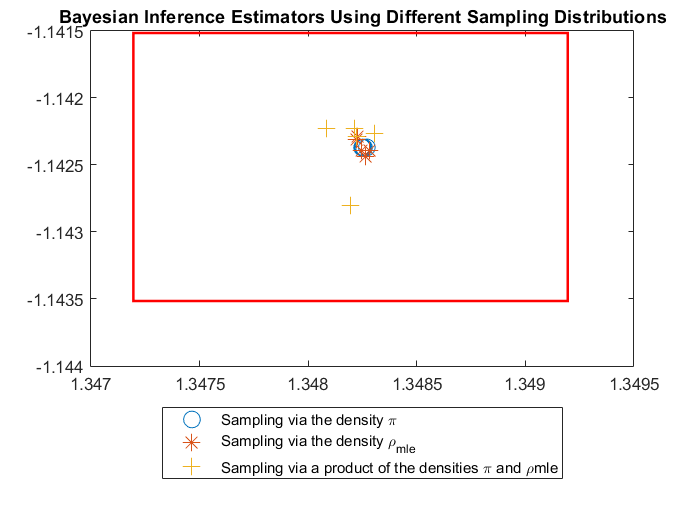

tableOfTimes = 3×2 table
                                        Runtime          SamplesTaken
                                   __________________    ____________

    Sampling from Density One      "151.8386 seconds"     "2621440"  
    Sampling from Density Two      "3.6665 seconds"       "40960"    
    Sampling from Density Three    "1.8114 seconds"       "20480"    


tstart = tic; 
M=100; %number of x data values
x=linspace(-2, 6, 100); %x data 
dim=2;
absTol=0.001;
densityChoice = [true true true];
BayesianFunction(M, x, dim, absTol, densityChoice)

toc(tstart)

Elapsed time is 157.915780 seconds.



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Calculating the first component of beta_hat via MLE density uses 4096 samples and takes 0.098798seconds.
Calculating the first component of beta_hat via the product of the standard normal density and the ML

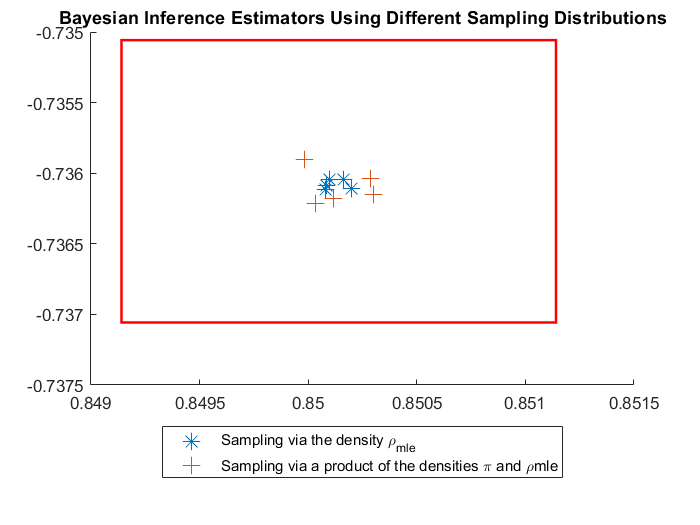

tableOfTimes = 3×2 table
                                        Runtime         SamplesTaken
                                   _________________    ____________

    Sampling from Density One      "N/A"                  "N/A"     
    Sampling from Density Two      "0.75928 seconds"      "14336"   
    Sampling from Density Three    "0.884 seconds"        "16384"   


tstart = tic; 
M=100; %number of x data values
x=linspace(-2, 6, 100); %x data 
dim=2;
absTol=0.001;
densityChoice = [false true true];
BayesianFunction(M, x, dim, absTol, densityChoice)

toc(tstart)

Elapsed time is 1.951375 seconds.


return

M=100; %number of x data values
x=linspace(-2, 6, 100); %x data 
dim=2;
absTol=0.001;
densityChoice = [true true false];
BayesianFunction_BAD(M, x, dim, absTol, densityChoice)